# DD2423 Lab1

clc
clear

## 1.3 Basis functions

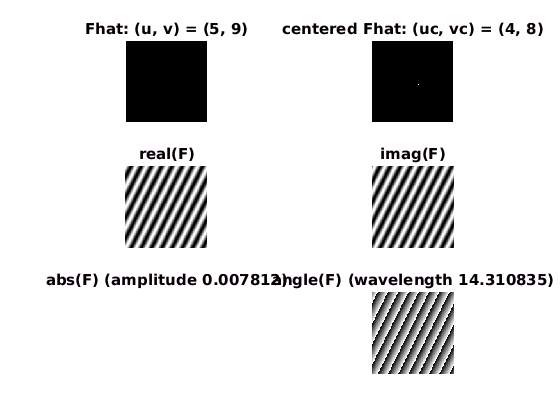

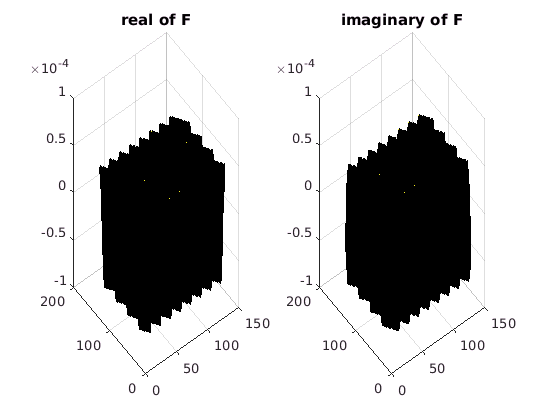

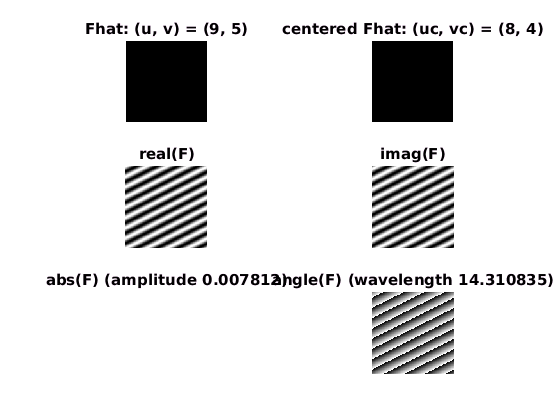

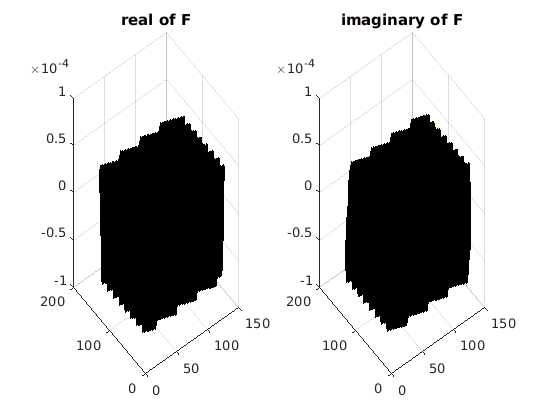

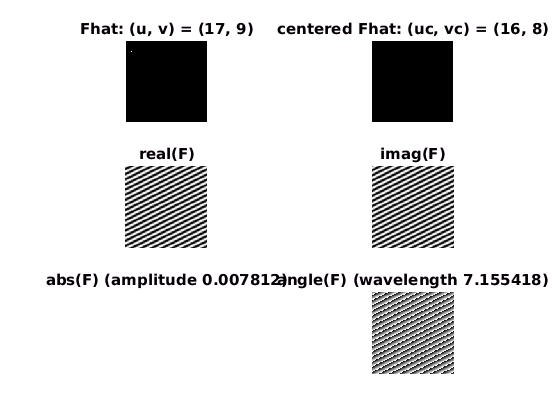

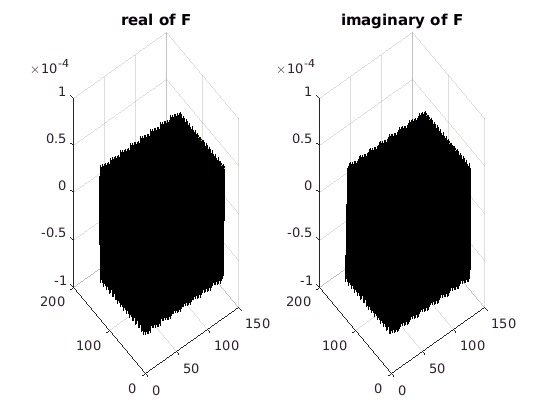

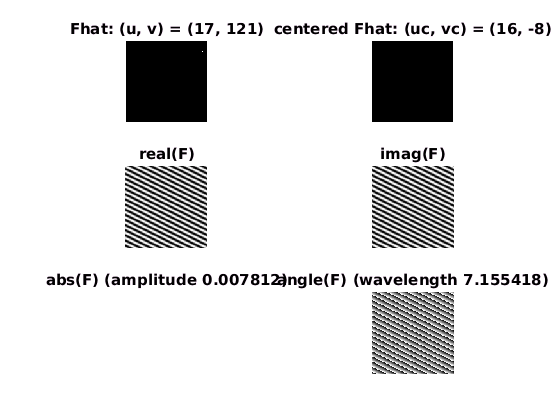

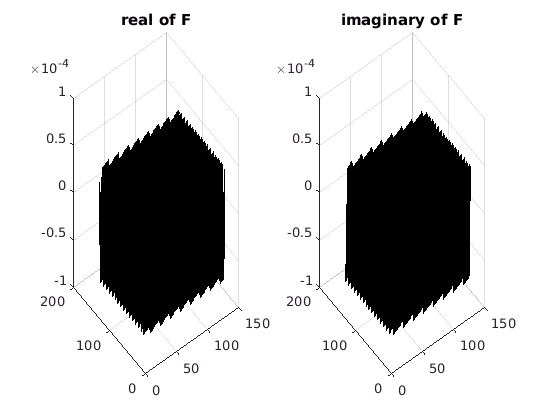

pq = cat(3, [5, 9], [9, 5], [17, 9], [17, 121], [5, 1], [125, 1]);%!Change pixel to play around!
for i = 1 : size(pq, 3);
    u = pq(1, 1, i);
    v = pq(1, 2, i);
    sz = 128;
    figure(i);
    fftwave(u, v, sz);
    % saveas(gcf,['./plot/Lab1_1.3_Q1_fig', num2str(i),'.png'],'png');
    
    figure(10+i)
    Fhat = zeros(sz);
    Fhat(u, v) = 1;
    F = ifft2(Fhat);
    Fabsmax = max(abs(F(:)));
    subplot(1,2,1)
    surf(real(F))
    title('real of F')
    subplot(1,2,2)
    surf(imag(F))
    title('imaginary of F')
    % saveas(gcf,['./plot/Lab1_1.3_Q1_fig', num2str(i),'-wave.png'],'png');
end

## 1.4 Linearity

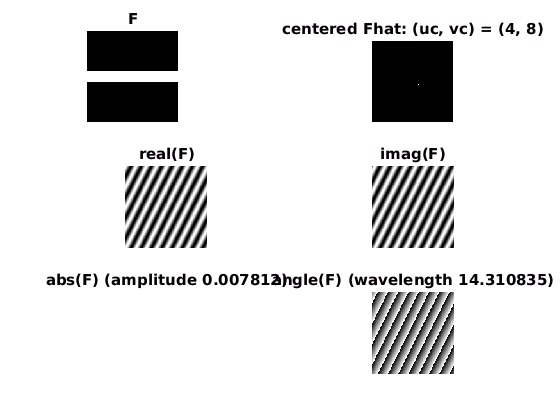

clc
clear

figure(1)
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

subplot(3, 3, 1);
showgrey(F);
title('F')

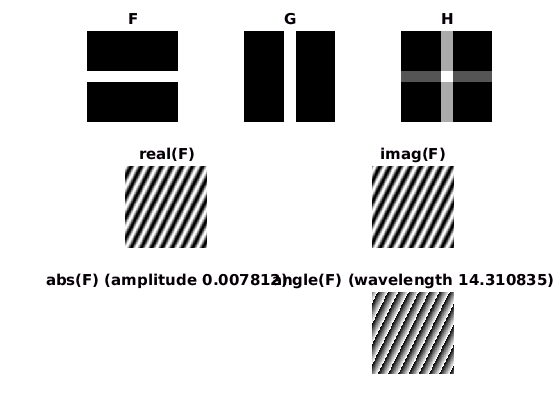

subplot(3, 3, 2);
showgrey(G);
title('G')
subplot(3, 3, 3);
showgrey(H);
title('H')

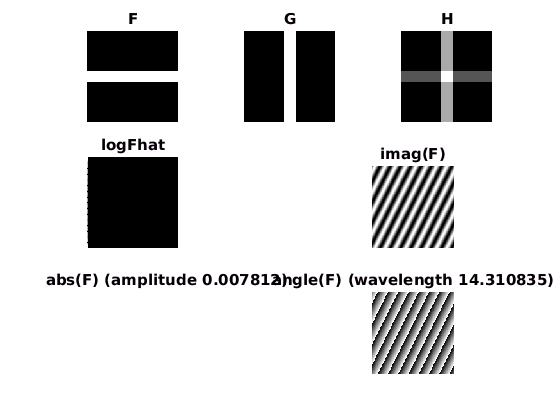


Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

subplot(3, 3, 4);
showgrey(log(1 + abs(Fhat)));
title('logFhat')

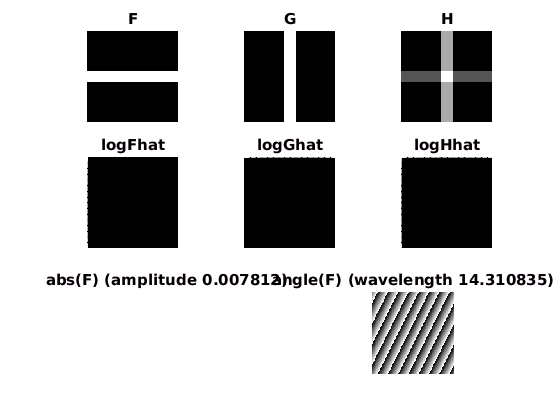

subplot(3, 3, 5);
showgrey(log(1 + abs(Ghat)));
title('logGhat')
subplot(3, 3, 6);
showgrey(log(1 + abs(Hhat)));
title('logHhat')

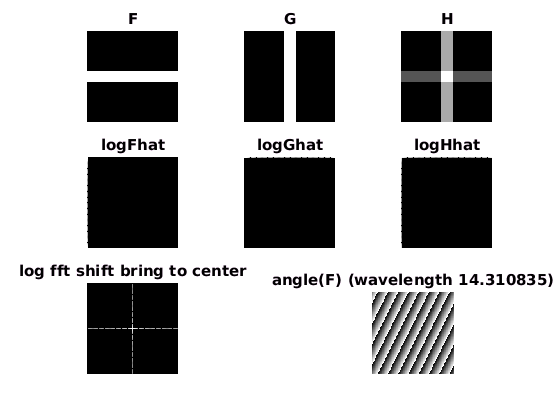


subplot(3, 3, 7);
showgrey(log(1 + abs(fftshift(Hhat))));
title('log fft shift bring to center')

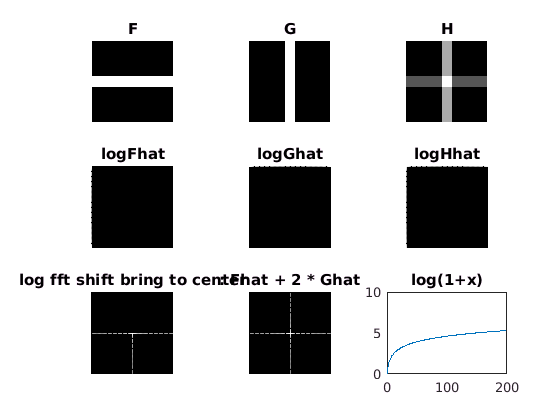


subplot(3, 3, 8);
showgrey(log(1 + abs(fftshift(Fhat + 2 * Ghat))));
title(': Fhat + 2 * Ghat')

% log figure
subplot(3, 3, 9);
plot(0:200, log([0:200]+1));
title('log(1+x)')


% DISPLAY THE IMAGES WITHOUT APPLYING LOG?

## 1.5 Multiplication

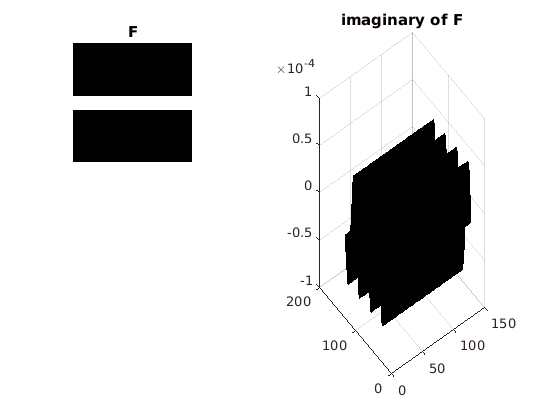

clc
clear
figure(15)

F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
subplot(2, 3, 1);
showgrey(F);
title('F')

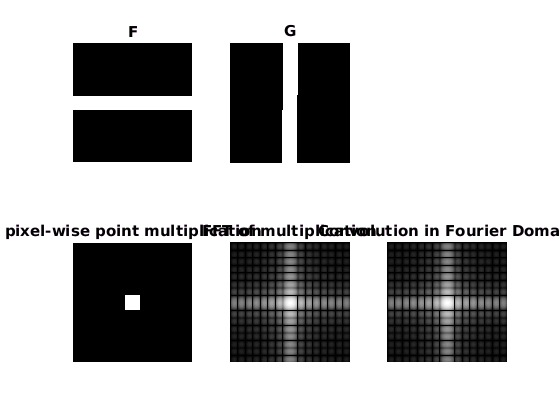

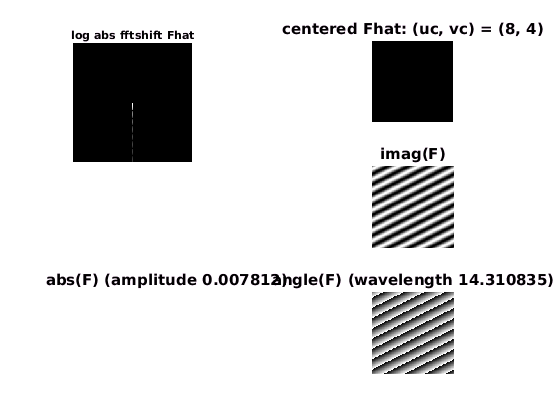

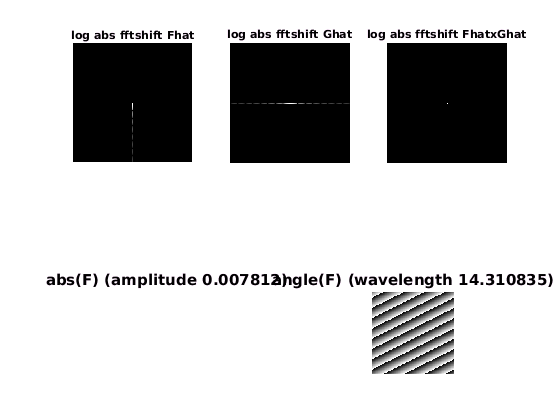

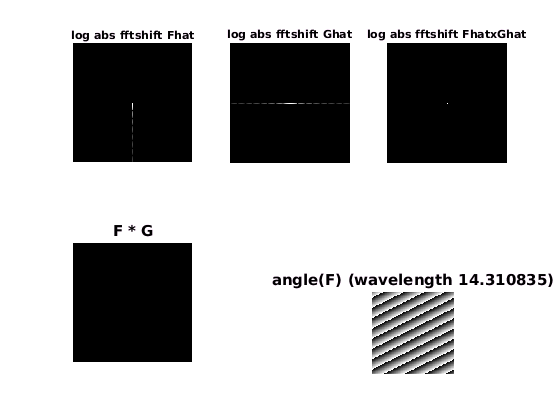

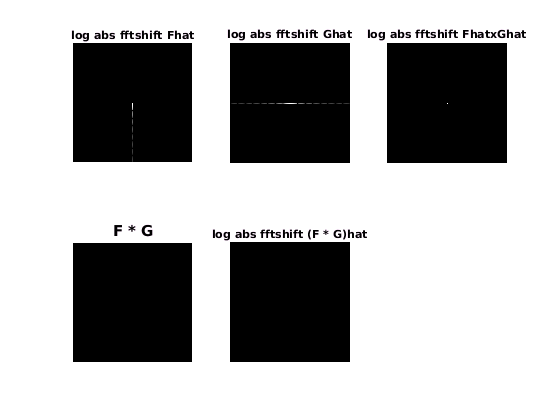

subplot(2, 3, 2);
showgrey(G);
title('G')
subplot(2, 3, 4);
showgrey(F .* G);
title('pixel-wise point multiplication')
subplot(2, 3, 5);
showfs(fft2(F .* G));%/128);
title('FFT of multiplication')

subplot(2, 3, 6)
Fhat = fft2(F)/128;
Ghat = fft2(G)/128;
Cs = conv2(fftshift(Fhat),fftshift(Ghat), 'same');
showfs(fftshift(Cs));
title('Convolution in Fourier Domain')

## 1.6 Scaling

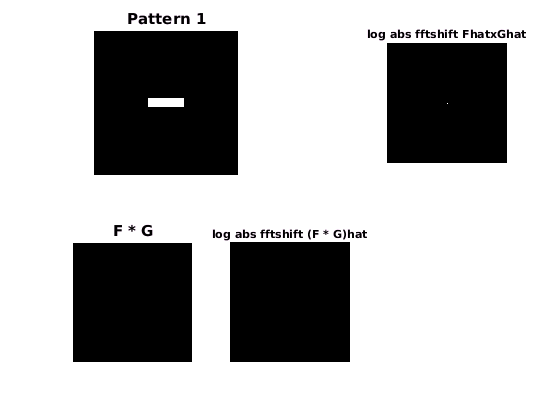

clc
clear

F = [ zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
   [ zeros(128, 48) ones(128, 32) zeros(128, 48)];

subplot(2, 2, 1);
showgrey(F);
title('Pattern 1');

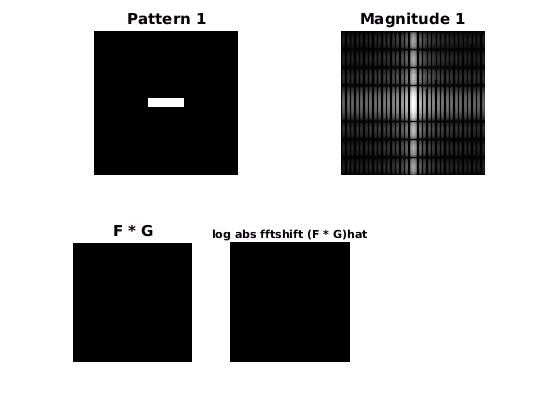


subplot(2, 2, 2);
showfs(fft2(F));
title('Magnitude 1')

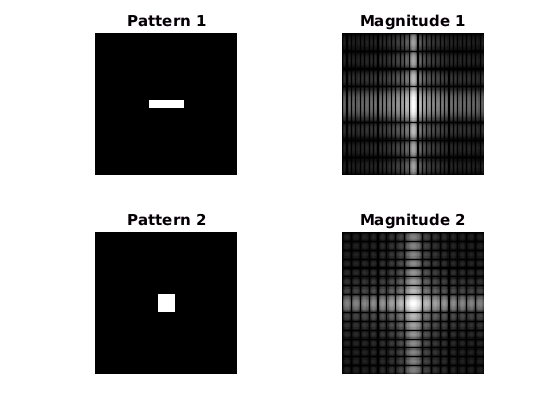


subplot(2, 2, 3);
P2 = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = P2';
showgrey(P2 .* G);
title('Pattern 2')

subplot(2, 2, 4);
showfs(fft2(P2 .* G));
title('Magnitude 2')

## 1.7 Rotation

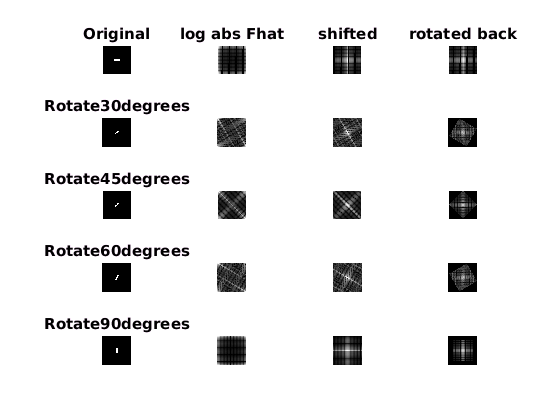

figure(17)

F = [ zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
   [ zeros(128, 48) ones(128, 32) zeros(128, 48)];
subplot( 5, 4, 1)
showgrey(F);
title('Original')

subplot( 5, 4, 2)
Fhat = fft2(F);
showgrey(log(1 + abs(Fhat)));
title('log abs Fhat');

subplot( 5, 4, 3)
Fhat = fft2(F);
showfs(Fhat);
title('shifted');

subplot( 5, 4, 4)
showfs(Fhat);
title('rotated back');

i = 1;
for alpha = [30, 45, 60, 90]
   i = i + 4;
   subplot( 5, 4, i)
   G = rot(F, alpha);
   showgrey(G)
   title(['Rotate', num2str(alpha),'degrees']);
   %axis on

   subplot( 5, 4, i+1)
   Ghat = fft2(G);
   showgrey(log(1 + abs(Ghat)));
   %title('log abs of Ghat');
   
   subplot( 5, 4, i+2)
   Fhat = fft2(G);
   showfs(Ghat);
   %title('showfs');

   Hhat = rot(fftshift(Ghat), -alpha );
   subplot( 5, 4, i+3)
   showgrey(log(1 + abs(Hhat)));
   %title('log abs of shift back');
end

## 1.8 Plot reconstructions

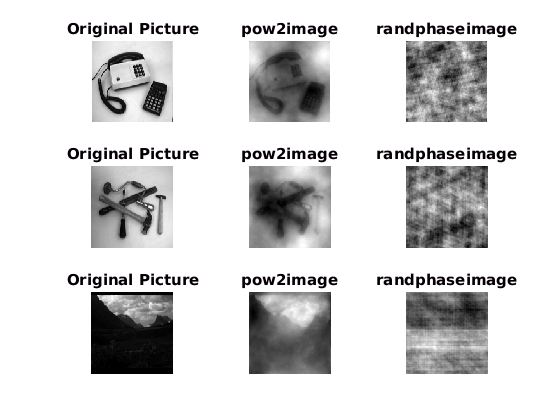

clc
clear
img = cat(3, phonecalc128, few128, nallo128);
a = 10^(-10);

for i = 1 : size(img,3)
    F = img(:,:,i);
    figure(18);
    subplot(3, 3, (i-1)*3+1);
    showgrey(F);
    title('Original Picture');
    
    subplot(3, 3, (i-1)*3+2);
    showgrey(pow2image(F, a));
    title(sprintf('pow2image')); 
    
    subplot(3, 3, (i-1)*3+3);
    showgrey(randphaseimage(F));
    title(sprintf('randphaseimage'));
    
end